%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% demo_graphical_learning_pagerank.m
%
% 75-minute graphical learning recitation, Example 1:
% PageRank on a toy web / citation network.
%
% Message to students:
%   From Griffin Ch. 4-5, we already know:
%   - graphs can be represented by adjacency matrices,
%   - eigenvectors can rank vertices,
%   - Markov chains / random walks / PageRank live on directed graphs.
%
% This script shows how those ideas become a real-world learning / ranking tool.
%
% Real-world interpretation:
%   Each node is a web page (or paper).
%   A directed edge i -> j means page i links to page j.
%   PageRank learns an importance score for every node from link structure alone.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;


%% ------------------------------------------------------------------------
% STEP 1. Build a small directed graph
% -------------------------------------------------------------------------
% We choose a small "web" with 10 pages. The structure is designed so that
% some pages have many incoming links but not all incoming links are equal.
% PageRank will distinguish "important because linked by important pages"
% from simply "many incoming links".

names = {'Home','News','Research','Course','Blog','Data','Tools','PaperA','PaperB','Contact'};

% Edge list: source -> target
s = [1 1 1 2 2 3 3 3 4 4 5 5 6 6 7 7 8 9 9 10];
t = [2 3 4 3 5 6 7 8 3 10 2 10 3 7 3 6 3 3 8 1];

G = digraph(s,t,[],names);
A = adjacency(G);        % sparse adjacency matrix; A(i,j)=1 if i->j
n = numnodes(G);


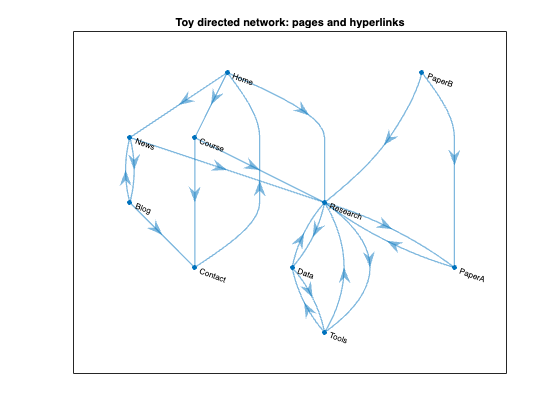

%% ------------------------------------------------------------------------
% STEP 2. Visualize the graph
% -------------------------------------------------------------------------
figure('Color','w','Name','PageRank: toy web graph');
p = plot(G,'Layout','layered','ArrowSize',12,'LineWidth',1.3);
title('Toy directed network: pages and hyperlinks');

%% ------------------------------------------------------------------------
% STEP 3. Build the transition matrix for a random surfer
% -------------------------------------------------------------------------
% Convention:
%   We want a column-stochastic matrix P such that x_{k+1} = P x_k,
%   where x_k is the probability distribution over nodes at step k.
%
% If page j has outgoing links to its neighbors, then the surfer at j chooses
% uniformly among those outgoing links.
%
% Column j of P therefore contains probabilities of leaving node j.

outdeg = outdegree(G);
P = zeros(n,n);
for j = 1:n
    nbrs = successors(G,j);     % pages linked *from* j
    if isempty(nbrs)
        % Dangling node: if a page has no outgoing links, use uniform jump
        P(:,j) = 1/n;
    else
        P(nbrs,j) = 1/numel(nbrs);
    end
end

% Check column-stochastic property
fprintf('Maximum column-sum error in P: %.2e\n', max(abs(sum(P,1)-1)));

Maximum column-sum error in P: 0.00e+00


%% ------------------------------------------------------------------------
% STEP 4. Add teleportation and run PageRank power iteration
% -------------------------------------------------------------------------
alpha = 0.85;                    % standard damping parameter
v = ones(n,1)/n;                 % teleportation distribution (uniform)
Gmat = alpha*P + (1-alpha)*(v*ones(1,n));

% Power iteration
x = ones(n,1)/n;                 % initial probability vector
maxIter = 200;
tol = 1e-12;
history = zeros(maxIter,1);
for k = 1:maxIter
    x_new = Gmat*x;
    history(k) = norm(x_new-x,1);
    x = x_new;
    if history(k) < tol
        history = history(1:k);
        break;
    end
end
pagerank_scores = x/sum(x);      % normalize to sum to 1 exactly

fprintf('\nPageRank scores:\n');


PageRank scores:


for i = 1:n
    fprintf('  %-8s  %.4f\n', names{i}, pagerank_scores(i));
end

  Home      0.0504
  News      0.0435
  Research  0.3143
  Course    0.0293
  Blog      0.0335
  Data      0.1809
  Tools     0.1809
  PaperA    0.1104
  PaperB    0.0150
  Contact   0.0417


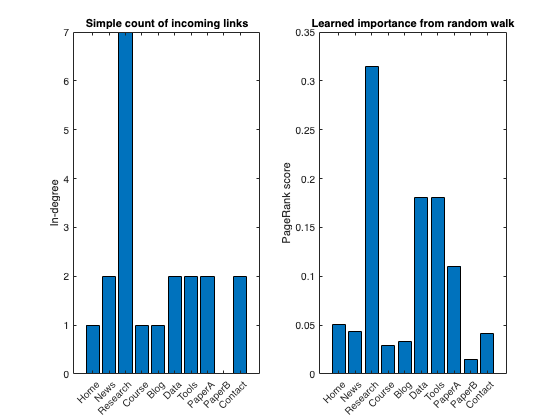

%% ------------------------------------------------------------------------
% STEP 5. Compare PageRank with simple in-degree
% -------------------------------------------------------------------------
indeg = indegree(G);

figure('Color','w','Name','PageRank vs indegree');
subplot(1,2,1);
bar(indeg);
xticks(1:n); xticklabels(names); xtickangle(45);
ylabel('In-degree');
title('Simple count of incoming links');

subplot(1,2,2);
bar(pagerank_scores);
xticks(1:n); xticklabels(names); xtickangle(45);
ylabel('PageRank score');
title('Learned importance from random walk');

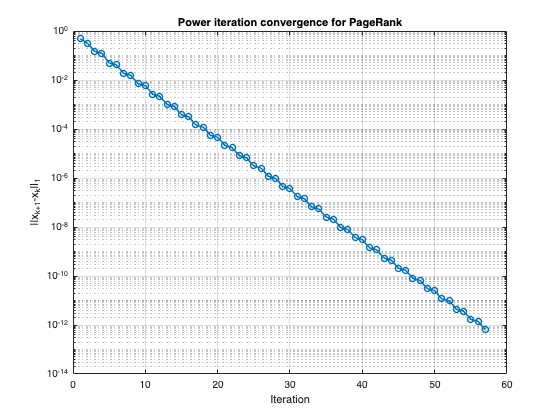

%% ------------------------------------------------------------------------
% STEP 6. Show convergence of the power method
% -------------------------------------------------------------------------
figure('Color','w','Name','PageRank power iteration convergence');
semilogy(history,'o-','LineWidth',1.5);
xlabel('Iteration');
ylabel('||x_{k+1}-x_k||_1');
title('Power iteration convergence for PageRank');
grid on;

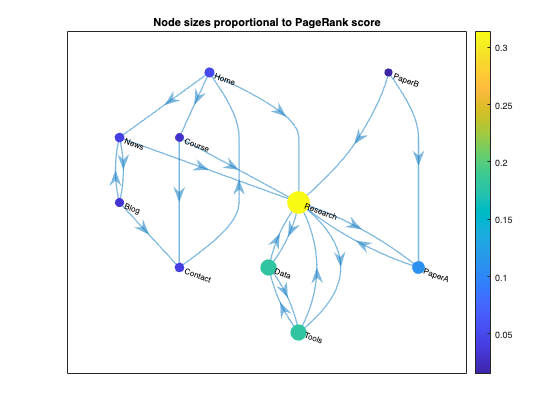

%% ------------------------------------------------------------------------
% STEP 7. Visualize ranks on the graph
% -------------------------------------------------------------------------
figure('Color','w','Name','PageRank on graph');
p2 = plot(G,'Layout','layered','ArrowSize',12,'LineWidth',1.3);
title('Node sizes proportional to PageRank score');

% Rescale marker sizes for display
minSize = 6; maxSize = 18;
sz = minSize + (pagerank_scores - min(pagerank_scores)) ./ ...
    (max(pagerank_scores)-min(pagerank_scores)+eps) * (maxSize-minSize);

p2.MarkerSize = sz*1.2;
% Show high-ranked nodes in red, low-ranked in blue via CData
p2.NodeCData = pagerank_scores;
colormap(parula);
colorbar;

%% ------------------------------------------------------------------------
% TEACHING NOTES
% -------------------------------------------------------------------------
% 1. PageRank is not just counting incoming links. It uses the idea that
%    links from important pages should count more.
% 2. That is exactly an eigenvector / fixed-point idea from Griffin Ch. 5.
% 3. The random-walk interpretation is also exactly Griffin Ch. 5:
%       x_{k+1} = G x_k,  stationary vector x* satisfies x*=Gx*.
% 4. So a famous real-world algorithm (Google search ranking) uses nothing
%    beyond: adjacency matrix + stochastic matrix + stationary vector.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
